# Interpolate Poses For Dubins Path

Create a `dubinsConnection` object.

dubConnObj = dubinsConnection;

Define start and goal poses as `[x y theta]` vectors.

startPose = [0 0 0];
goalPose = [1 1 pi];

Calculate a valid path segment to connect the poses.

[pathSegObj,pathCosts] = connect(dubConnObj,startPose,goalPose);

Show the generated path.

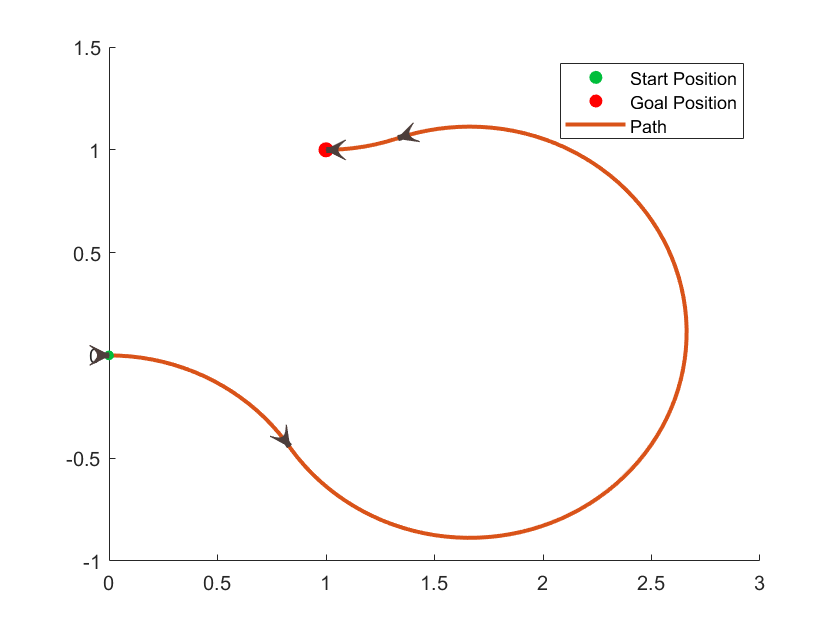

show(pathSegObj{1})

Interpolate poses along the path. Get a pose every 0.2 meters, including the transitions between turns.

length = pathSegObj{1}.Length;
poses = interpolate(pathSegObj{1},0:0.2:length)

poses =          0         0         0
    0.1987   -0.0199    6.0832
    0.3894   -0.0789    5.8832
    0.5646   -0.1747    5.6832
    0.7174   -0.3033    5.4832
    0.8309   -0.4436    5.3024
    0.8418   -0.4595    5.3216
    0.9718   -0.6110    5.5216
    1.1293   -0.7337    5.7216
    1.3081   -0.8226    5.9216


Use the [quiver](docid:matlab_ref.f31-504618) function to plot these poses.

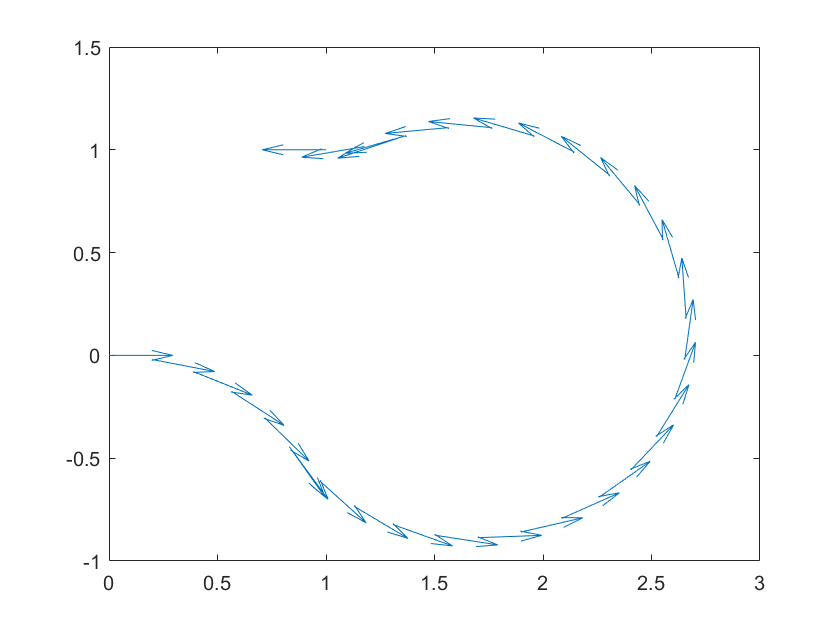

Error using matlab.internal.editor.figure.SerializedFigureState/serialize
Error while evaluating Figure SizeChangedFcn.



quiver(poses(:,1),poses(:,2),cos(poses(:,3)),sin(poses(:,3)),0.5)

*Copyright 2019 The MathWorks, Inc.*